# Corrélation

## Accès dossier et choix essai

% This part is specific to my organisation, I think you can forgot it ; ) 
Type = "DCC7SD";
Materiau = '4140';
Eprouvette ='3';
Numero = '1';
addpath('/home/tdelaselle/Documents/Codes/Codes-matlab/Fonctions');
repertoire_traitees = acces_donnees_traitees();
addpath(strcat(repertoire_traitees,'/',Type,'/',Materiau));
Naming = strcat(Type,'_',Materiau,'_',Eprouvette,'.',Numero);
load(strcat(Naming,'.mat'));

## Calcul

Paramètres

(Supprimer pré-trigger enlève 156 points)

% Settings 
nbreCH = 2; % Number of channels
pretrig = false; % Cut the pre-trigger or not
if pretrig == 1
    init = 156;
else
    init = 1;
end
impul = 300; % Choose the number of points from the beginning of the WF

% Comptage du nombre de waveforms par channel
channel = HDD.CH;
chNbre = zeros(nbreCH,1);
chNbre(1) = length(find(channel==1));
chNbre(2) = length(find(channel==2));
chNbre(3) = length(find(channel==3));
chNbre(4) = length(find(channel==4));
chNbre(5) = length(find(channel==5));
chNbre(6) = length(find(channel==6));

% Modif du dernier point de chaque WF (s'assurer qu'il n'y a pas de NaN)
% len = size(WF);
% for i = 1:len(2)
%     WF{end,i} = 0;
% end

% Running correlation between all the WF for each channel. 
for i = 1:chNbre(1)
    for j = (i+1):chNbre(1)
         [corr, t] = xcorr(WF.(strcat('1_',string(i)))(init:impul),WF.(strcat('1_',string(j)))(init:impul),'normalized');
         [Cor1(i,j), x] = max(corr);
         dt1(i,j) = t(x);
    end
end
for i = 1:chNbre(2)
    for j = (i+1):chNbre(2)
         [corr, t] = xcorr(WF.(strcat('2_',string(i)))(init:impul),WF.(strcat('2_',string(j)))(init:impul),'normalized');
         [Cor2(i,j), x] = max(corr);
         dt2(i,j) = t(x);
    end
end
for i = 1:chNbre(3)
    for j = (i+1):chNbre(3)
         [corr, t] = xcorr(WF.(strcat('3_',string(i)))(init:impul),WF.(strcat('3_',string(j)))(init:impul),'normalized');
         [Cor3(i,j), x] = max(corr);
         dt3(i,j) = t(x);
    end
end
for i = 1:chNbre(4)
    for j = (i+1):chNbre(4)
         [corr, t] = xcorr(WF.(strcat('4_',string(i)))(init:impul),WF.(strcat('4_',string(j)))(init:impul),'normalized');
         [Cor4(i,j), x] = max(corr);
         dt4(i,j) = t(x);
    end
end
for i = 1:chNbre(5)
    for j = (i+1):chNbre(5)
         [corr, t] = xcorr(WF.(strcat('5_',string(i)))(init:impul),WF.(strcat('5_',string(j)))(init:impul),'normalized');
         [Cor5(i,j), x] = max(corr);
         dt5(i,j) = t(x);
    end
end
for i = 1:chNbre(6)
    for j = (i+1):chNbre(6)
         [corr, t] = xcorr(WF.(strcat('6_',string(i)))(init:impul),WF.(strcat('6_',string(j)))(init:impul),'normalized');
         [Cor6(i,j), x] = max(corr);
         dt6(i,j) = t(x);
    end
end

## Affichage matrices

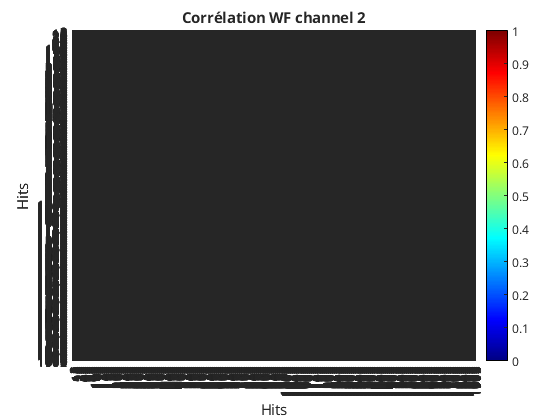

 ;
cha = 2;
figure();
if cha ==1
    heatmap(Cor1);
elseif cha==2
    heatmap(Cor2);
elseif cha==3 
    heatmap(Cor3);
elseif cha==4 
    heatmap(Cor4);
elseif cha==5 
    heatmap(Cor5);
elseif cha==6 
    heatmap(Cor6);
end
colormap jet;
title(strcat("Corrélation WF channel ",string(cha)));
xlabel('Hits');
ylabel('Hits');
caxis([0 1]);

## Statistiques # In development  ^^

Table des valeurs moyennes :

% chtable = [1; 2];
% % COCO2 = COCO;
% % COCO2(:,isnan(COCO2.Cor)) = [];
% cohmoy = [sum(COCO.Coh(1:kstock)/kstock); sum(COCO.Coh((kstock+1):len(1))/(len(1)-kstock))];
% cormoy = [sum(COCO.Cor(1:kstock)/kstock); sum(COCO.Cor((kstock+1):len(1))/(len(1)-kstock))];
% MOY = table(chtable,cohmoy,cormoy,'VariableNames',{'Ch', 'COHmoyenne', 'CORmoyenne'})

Nombre de corrélations/cohérences au dessus d'un seuil : 

% seuil = 0.95;
% cohseuil = [0;0];
% corseuil = [0;0];
% for i = 1:kstock
%     if COCO.Cor(i) >= seuil
%         corseuil(1) = corseuil(1)+1;
%     end
%     if COCO.Coh(i) >= seuil
%         cohseuil(1) = cohseuil(1)+1;
%     end
% end
% for i = (kstock+1):len(1)
%     if COCO.Cor(i) >= seuil
%         corseuil(2) = corseuil(2)+1;
%     end
%     if COCO.Coh(i) >= seuil
%         cohseuil(2) = cohseuil(2)+1;
%     end
% end
% nbseuil = table(chtable,cohseuil,corseuil,'VariableNames',{'Ch', 'Nbre coh > seuil', 'Nbre cor > seuil'})

## Sauvegarde

% this part saves the big matrices Cor et dt. It's specific to my organisation
repertoire_traitees = acces_donnees_traitees();
for i = 1:nbreCH
    save(strcat('/home/tdelaselle/Documents/Données_essais/Traitement_essais/',Type,'/',Materiau,'/',Naming,'.mat'),"pretrig","impul",strcat('Cor',string(i)),strcat('dt',string(i)),'-append');
end
"Sauvegardé !"

ans = "Sauvegardé !"